# Getting started with the MEDA Toolbox

**Authors:** Jose Camacho

**Last modification:** 7/Jan/2025

There are two ways to work with the MEDA toolbox: using the GUI (starting users) and using the commands (advanced users). The GUI is self explanatory. It incorporates helping messages to guide its use. To launch the GUI, type "MEDA" in the command line of Matlab after the installation. The commands provide of much more functionality. Each command includes helping information, that can be displayed by typing "help " in the command line of Matlab. This helping information includes examples. Also, in the "examples" directory, we include several real data examples.

## Using the GUI

Type MEDA and select one of the available tools.

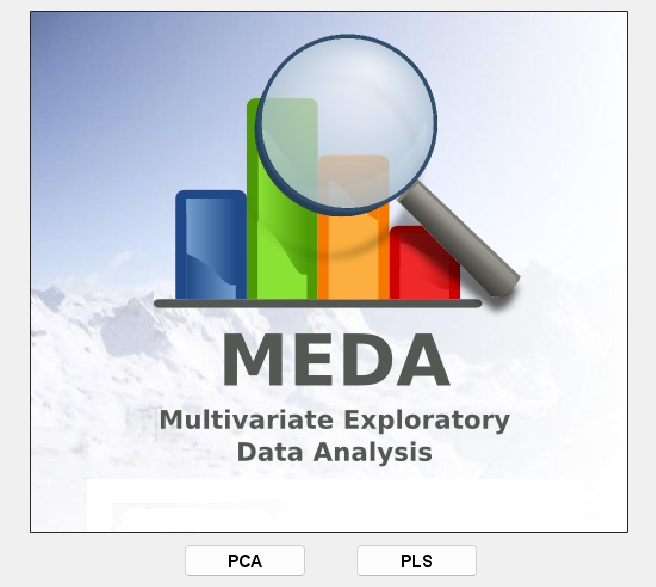

  MEDA

## Using routines: mspcPca

First, request help information:

  help mspcPCA

  Compute D-st and Q-st in PCA-based Multivariate Statistical Process 
  Control
 
  [Dst,Qst] = mspcPca(x) % minimum call
 
 
  INPUTS:
 
  x: [NxM] billinear data set for model fitting
 
 
  Optional INPUTS (parameters):
 
  'PCs': [1xA] Principal Components considered (e.g. pcs = 1:2 selects the
    first two PCs). By default, pcs = 1:rank(xcs)
 
  'ObsTest': [LxM] data set with the observations to be compared. These data 
    are preprocessed in the same way than calibration data
 
  'Preprocessing': [1x1] preprocesing of the data
        0: no preprocessing
        1: mean centering
        2: autoscaling (default) 
 
  'Option': (str or num) options for data plotting: binary code of the form 'abc' for:
        a:
            0: no plots
            1: plot MSPC charts
        b:
            0: scatter plot
            1: bar plot of each single statistic
        c:
            0: plot calibration and test data
            1: plot only test data 
    By deafult, o

The easiest way to try one routine is to copy and paste an example provided in the helping information. In the example, we generate a random matrix 100 x 10 for model building, and a test dataset 10 x 10 with five normal observations and five anomalous, then we evaluate the data with Multivariate Statistical Process Control (MSPC) based on Principal Component Analysis (PCA). 

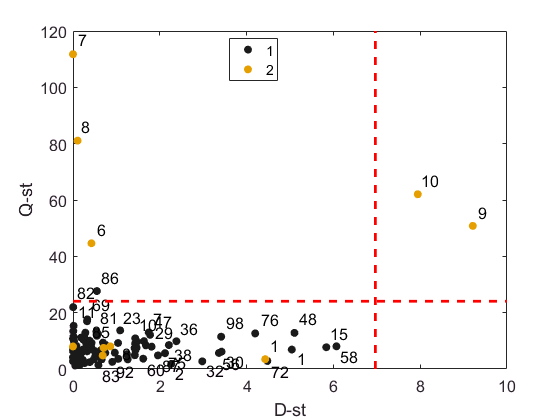

  nobs = 100;
  nvars = 10;
  nPCs = 1;
  X = simuleMV(nobs,nvars,'LevelCorr',6);
  
  pcs = 1:nPCs;
  
  nobst = 10;
  test = simuleMV(nobst,nvars,'LevelCorr',6,'Covar',cov(X)*(nobst-1));
  test(6:10,:) = 3*test(6:10,:);
  
  [Dst,Qst,Dstt,Qstt] = mspcPca(X,'PCs',pcs,'ObsTest',test);

## Using routines: asca

First, request help information:

  help asca

  asca is a data analysis algorithm for designed experiments. The input is 
  a General Linear Models (GLM) factorization of the data (done with parglm 
  and stored in parglmo) and the code applies Principal Component Analysis 
  to the factor/interaction matrices.
 
  ascao = asca(parglmo)   % minimum call
 
 
  See also: parglm, apca, gasca, vasca, createDesign
 
 
  INPUTS:
 
  parglmo (structure): structure with the GLM decomposition with factor and 
  interaction matrices, p-values and explained variance. 
 
 
  OUTPUTS:
 
  ascao (structure): structure that contains scores, loadings, singular
  values and projections of the factors and interactions.
 
 
  EXAMPLE OF USE (copy and paste the code in the command line)
    Random data, two factors, with 4 and 3 levels, but only the first one 
    is si

EXAMPLE OF USE (copy and paste the code in the command line) Random data, two factors, with 4 and 3 levels, but only the first one is significative, and 4 replicates:

  reps = 4;
  vars = 10;
  levels = {[1,2,3,4],[1,2,3]};
  
  F = createDesign(levels,'Replicates',reps);
  
  X = zeros(size(F,1),vars);
  for i = 1:length(levels{1})
      X(find(F(:,1) == levels{1}(i)),:) = simuleMV(length(find(F(:,1) == levels{1}(i))),vars,'LevelCorr',8) + repmat(randn(1,vars),length(find(F(:,1) == levels{1}(i))),1);
  end
  
  [table, parglmo] = parglm(X, F);

Starting parallel pool (parpool) using the 'local' profile ... connected to 8 workers.


  table

table =       Source       SumSq     PercSumSq    df    MeanSq      F        Pvalue 
    ___________    ______    _________    __    ______    ______    ________
    'Mean'          10518     35.876       1     10518       NaN         NaN
    'Factor 1'      15561     53.076       3      5187    71.396    0.000999
    'Factor 2'     187.55    0.63971       2    93.776    1.2908     0.23576
    'Residuals'    3051.4     10.408      42    72.651       NaN         NaN
    'Total'         29318        100      48     610.8       NaN         NaN

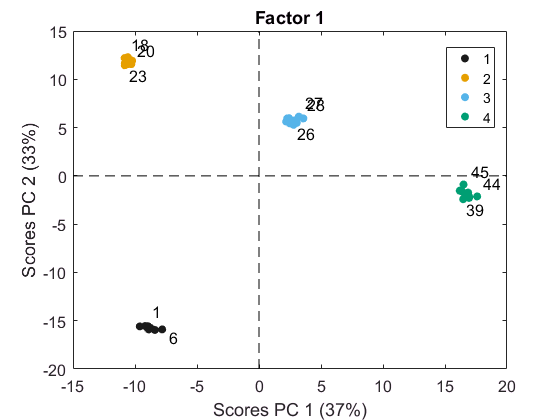

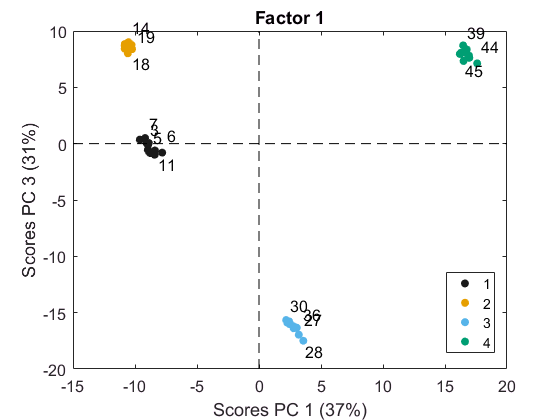

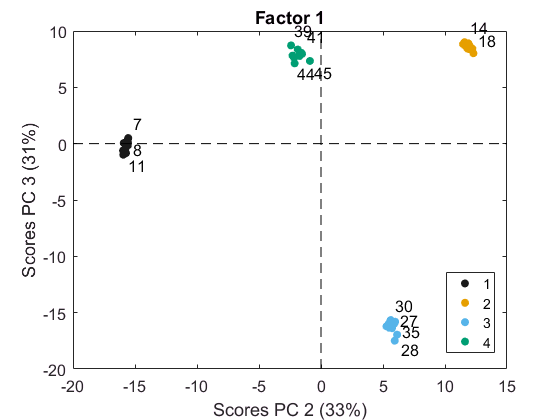

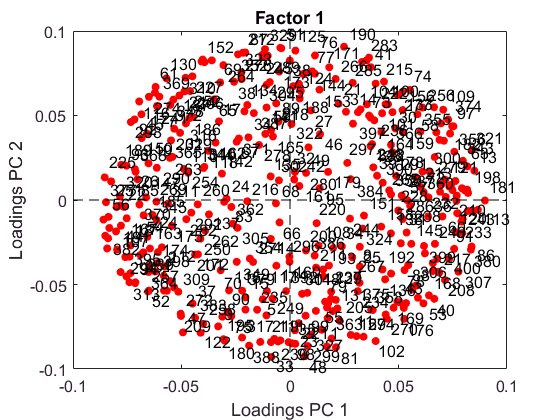

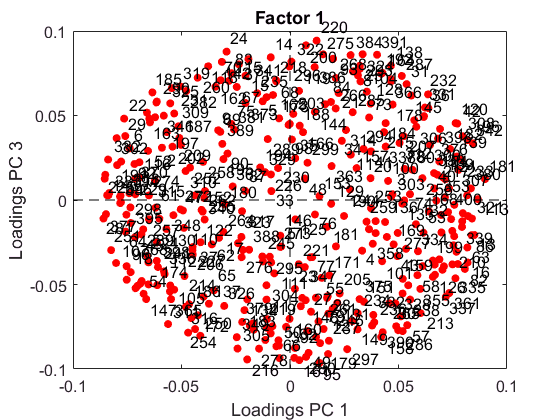

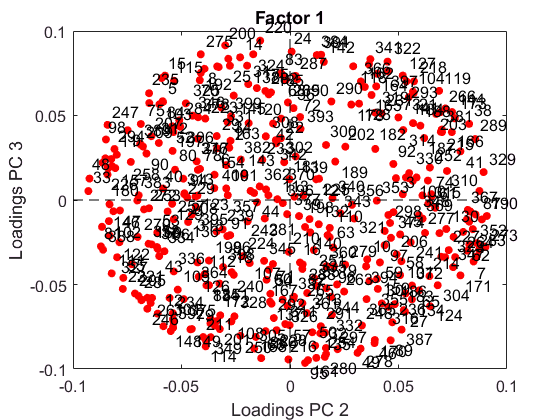

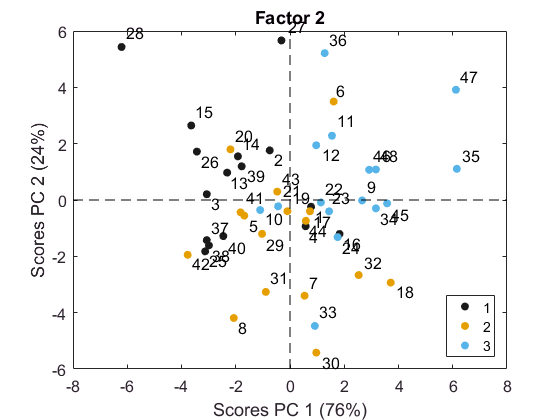

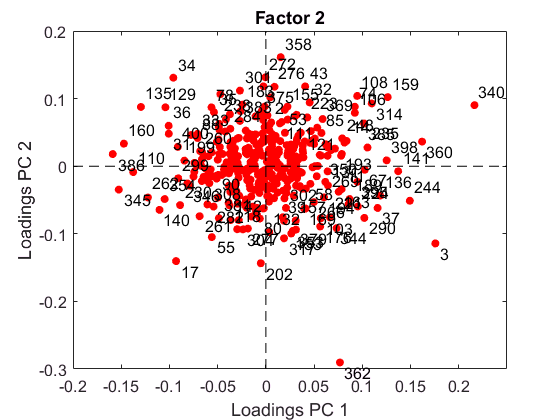

  
  ascao = asca(parglmo);
  
  for i=1:2 % Note, the second factor is only shown for the sake of illustration, but non-significant factors should not be visualized
    scores(ascao.factors{i},'Title',sprintf('Factor %d',i),'ObsClass',ascao.design(:,i));
    loadings(ascao.factors{i},'Title',sprintf('Factor %d',i));
  end

## Copyright (C) 2024  Universidad de Granada

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program.  If not, see <http://www.gnu.org/licenses/>.